## **Prerequisites**

clear 
clc
% Add YALMIP to local path
addpath(genpath("C:\Users\amato\OneDrive\Documenten\TU\MSC S&C\Year 1\Q3 23-24\MPC"))

## **Continuous Time State Space (LQR Design)**

*The first piece of code consists of replicating the CT LQR design in the main paper from which we derive our system dynamics (Bencatel et al.)*

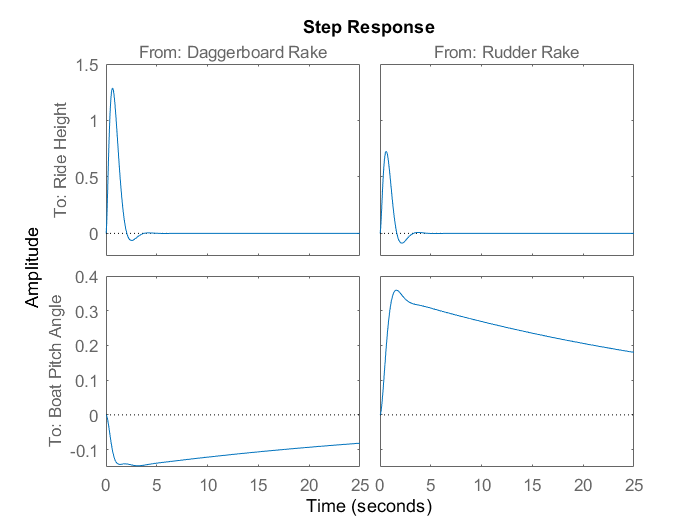

% Continuous Time State Space of AC45
A = [-0.135 -4.905 0.125 0.176 4.902;
      0.180 -7.132 -1.419 -0.075 -7.132;
      0 -0.768 -1.315 0.014 -0.768;
      0 10.85 0 0 0;
      0 0 1 0 0]; 
B = [-4.078 4.555 -1.254 0 0;
     -0.226 2.566 2.378 0 0]';
C = [0 0 0 1 0;
     0 0 0 0 1];
D = [];

% Define Augmented SS

A_tilde = [A zeros(5, 2);
           C zeros(2, 2)];
B_tilde = [B;
           zeros(2, 2)];
C_tilde = [C zeros(2, 2)];
D_tilde = D;

sys = ss(A_tilde, B_tilde, C_tilde, D_tilde);

% Define Q and R
Q_theta = 5;
Q_ez = 0.5;
Q_etheta = 0.005;
Q = blkdiag(zeros(4), Q_theta, Q_ez, Q_etheta);
R = eye(2);

% Obtain LQR Gains
[K, ~, ~] = lqr(sys, Q, R);
K_x = K(:, 1:5);
K_z = K(:, 6);
K_theta = K(:, 7);

% Simulate (NOT SAME CONTROL LAW AS IN PAPER)
sys1 = ss(A_tilde-B_tilde*K,B_tilde,C_tilde,D_tilde);

sys1.InputName = {'Daggerboard Rake', 'Rudder Rake'};
sys1.StateName = {'Boat Hydrodynamic Speed', 'Flight Path Angle', 'Angular Velocity', 'Ride Height', 'Boat Pitch Angle', 'Error_z', 'Error_theta'};
sys1.OutputName = {'Ride Height', 'Boat Pitch Angle'};
[yout,tout,xout] = step(sys1, 25);

% Plot
step(sys1, 25);


% Obtain natural frequency
[wn, zeta] = damp(sys1);

%Choose Sampling Period 
h = 0.5; %in seconds

## **Discretize System using ZOH and sampling period h (without disturbance)**

%Create DT SS
Psi=expm(A*h);
fun=@(t)expm(A.*t);
Gamma=integral(fun,0,h,'ArrayValued',1)*B;

%Check Controllability
CO_dt = ctrb(Psi,Gamma); %Controllability Matrix
if rank(CO_dt) == size(Psi,1) && min(svd(CO_dt)) >= 0.001
    fprintf("DT System Controllable :)")
else
    warning("DT System not Controllable :(")
end

DT System Controllable :)


%Check Observability
OBS_dt = obsv(Psi,C); %Obs matrix
if rank(OBS_dt) == size(Psi,1) && min(svd(OBS_dt)) >= 0.001
    fprintf("DT System Observable :)")
else
    warning("DT System not Observable :(")
end

DT System Observable :)

## **Discrete Time State Space**

AC45.A = Psi;
AC45.B = Gamma;
AC45.C = C;
AC45.D = D;

% Definition of system dimensions
dim.nx = size(AC45.A, 1);    % state dimension
dim.ny = size(AC45.C, 1);    % output dimension
dim.nu = size(AC45.B, 2);    % input dimension
dim.N = 20;                  % receding horizon
dim.d = 1;                   % disturbance dimension

## **Prediction Model**

%Prediction matrix from initial state
T = zeros(dim.nx*(dim.N+1),dim.nx);
for k = 0:dim.N
    T(k*dim.nx+1:(k+1)*dim.nx,:) = AC45.A^k;
end

%Prediction matrix from input
S = zeros(dim.nx*(dim.N+1),dim.nu*(dim.N));
for k = 1:dim.N
    for i = 0:k-1
        S(k*dim.nx+1:(k+1)*dim.nx,i*dim.nu+1:(i+1)*dim.nu) = AC45.A^(k-1-i)*AC45.B;
    end
end

predmod.T = T;
predmod.S = S;

## **Weights and Cost Function**

%Definition of quadratic cost function
weight.Q = diag([0.1 10 1 100 1]);   %weight on output
weight.R = diag([1 0.1]);               %weight on input

%Solve DARE
[P,K,L] = idare(Psi,Gamma,weight.Q,weight.R); 
K = -K; weight.P=P;

%Generate Cost Function
Qbar = blkdiag(kron(eye(dim.N),weight.Q),weight.P); 
Rbar=kron(eye(dim.N),weight.R); 
H=S'*Qbar*S+Rbar;
mu_x0=S'*Qbar*T;
mu_xref=-S'*Qbar*kron(ones(dim.N+1,1),eye(dim.nx));
mu_uref=-Rbar*kron(ones(dim.N,1),eye(dim.nu));
mu=[mu_x0 mu_xref mu_uref];

## Constraints

%Input Constraints
F1 = [0 1 0 0 -1; 
      0 -1 0 0 1; 
      0 0 0 0 0; 
      0 0 0 0 0];
E1 = [1 0;-1 0;0 1;0 -1];
e1 = [12;12;5;5];

%Tight State Constraints
F2 = [0 0 0 1 0;
      0 0 0 -1 0];
e2 = [0.5; 0.315];

%Loose State Constraints
F3 = [0 0 0 0 1; %theta (pitch angle)
      0 0 0 0 -1;
      1 0 0 0 0; %V_H (Hydrodynamic speed)
      -1 0 0 0 0; 
      0 1 0 0 0; %gamma (flight path angle)
      0 -1 0 0 0;
      0 0 1 0 0; %q (angular velocity)
      0 0 -1 0 0];
e3 = [20; 20; 
      5; 5; %m/s
      20;20; 
      20; 20];

%Compact notation of constraints
F =[F1; F2; F3]; E =[E1; zeros(2,2); zeros(8,2)];
e = [e1;e2;e3];

## Terminal Set

*We employ a hyperrhombus as an outer approximation of the elliptic terminal set. The vertices of the rhombus are constructed using the fact that the eigenvalues of P dictate the position where the eigenvectors intersect the ellipse boundary.*

%(Orthogonally) Diagonalize P
[V_p,D_p] = eig(P); %Check for x'TPx instead of 1/2x'TPx, numerically more reliable
V_p'*V_p %Visually check that V_p is an orthogonal basis, i.e. product is identity

ans =     1.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0000    1.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    1.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000    1.0000



c = 2; %Level curve of your choice, iterate

%Define hyperrhombus vertices approximating ellipsoid
rh_vert = 2*(inv(D_p)*(c*ones(size(D_p,1),1))); %Construct column vector of vertices

%Transform coordinates for both signs
rh_vert_tf = V_p*rh_vert;

%Check constraints, per region
if F*rh_vert_tf + E*(K*rh_vert_tf) <= e
    fprintf('Constraints are satisfied')
else
    warning('Constraints are not satisfied')
end

Constraints are satisfied

## Optimal Control Problem (reference tracking):

%Request simulation time
prompt = "Input simulation time: ";
T_sim = input(prompt)

T_sim = 10


% Initialize Results
x=zeros(dim.nx,T_sim+1); x(:,1)=[0, 0, 0, 0, 0]; %Initial condition
u_rec = zeros(dim.nu,T_sim);
AC45.y_ref=[0.3;0]; %Output target
y=zeros(dim.ny,T_sim);
dhat=zeros(dim.ny,T_sim+1); dhat(:,1)=zeros(dim.ny,1); %Estimated disturbance
AC45.d=[0;0];

%Terminal Set, last lines of S and T (i.e., x(N))
constraints.Ae=predmod.S(end-dim.nx+1:end,:); 
constraints.be=predmod.T(end-dim.nx+1:end,:);

%Concatenate Constraint LMIs
F_diag = kron(eye(dim.N),F); %block diagonal F matrix
E_diag = kron(eye(dim.N),E); %block diagonal E matrix
e_concat = kron(ones(dim.N,1),e);

%Start opt. time cumulative
sol_data.yalmiptime=0; sol_data.solvertime=0;

% Receding horizon implementation
for k = 1:T_sim
    x_0 = x(:,k); 
    
    %%OPTIMAL TARGET SELECTION
    %Define Optimization Variables
    x_r = sdpvar(dim.nx,1); u_r = sdpvar(dim.nu,1);
    %Define Constraints
    ots.cons_mat=[eye(dim.nx) - AC45.A, -AC45.B; AC45.C, zeros(dim.ny,dim.nu)]; 
    ots.cons_ref=[ots.cons_mat*[x_r;u_r]==[zeros(dim.nx,1);AC45.y_ref-dhat(:,k)]];
    ots.cons_state=[F*x_r + E*u_r <= e];
    ots.cons_all=[ots.cons_ref; ots.cons_state];
    %Define Objective
    ots.obj = [norm(u_r)];
    %% Solve OTS
    ops =  sdpsettings('verbose',0);                         
    sol_ots = optimize(ots.cons_all,ots.obj, ops);              
    % Analyze error flags
    if sol_ots.problem ~ 0
        warning('Something went wrong!');
        sol_ots.info
        yalmiperror(sol_ots.problem)
        warning('Loop Terminated!');
        break
    end
    %Extract values of minimizer: reference input and -state
    u_r=value(u_r); x_r=value(x_r);
    
    %% OPTIMAL CONTROL PROBLEM (with YALMIP)
    u_con = sdpvar(dim.nu*dim.N,1);                          %define optimization variable
    x_N = constraints.Ae*u_con + constraints.be*x_0;         %Terminal State
    %Constraints: terminal set and general constraints
    constraints.terminal = [(x_N-x_r)'*P*(x_N-x_r) <= c];    
    constraints.state = [F_diag*T(dim.nx+1:end,:)*x_0 + (F_diag*S(dim.nx+1:end,:)+E_diag)*u_con <= e_concat];
    constraints.all = [constraints.terminal;constraints.state];
    %Objective Function
    Objective = 0.5*u_con'*H*u_con+(mu*[x_0; x_r; u_r])'*u_con;%define objective function
    %Optimize
    ops =  sdpsettings('verbose',0,'cachesolvers',1,'saveduals',0);                        
    sol = optimize(constraints.all,Objective, ops);          %solve the problem
    % Analyze error flags
    if sol.problem ~ 0
        warning('Something went wrong!');
        sol.info
        yalmiperror(sol.problem)
    end
    %Save YALMIP and Solvertime
    sol_data.yalmiptime = sol_data.yalmiptime + sol.yalmiptime;
    sol_data.solvertime = sol_data.solvertime + sol.solvertime;
    %Extract solution
    u_con=value(u_con);                                       
    % Select the first input only
    u_rec(1:2,k)=u_con(1:2);
    clear u_con

    % Compute the state/output evolution (state feedback)
    x(:,k+1)=AC45.A*x_0 + AC45.B*u_rec(1:2,k);
    y(:,k)=AC45.C*x(:,k) + AC45.d + 0.01*randn(dim.ny,1);
    
    %Compute disturbance estimation
    Ldhat=[0.5 0; 0 0.5];       
    dhat(:,k+1)=dhat(:,k)+Ldhat*(y(:,k)-AC45.C*x(:,k+1)-dhat(:,k));
    
end

disp('Average Yalmip and Solver time')

Average Yalmip and Solver time


sol_data.yalmiptime/T_sim

ans = 0.2807

sol_data.solvertime/T_sim

ans = 0.3024

**Plots**

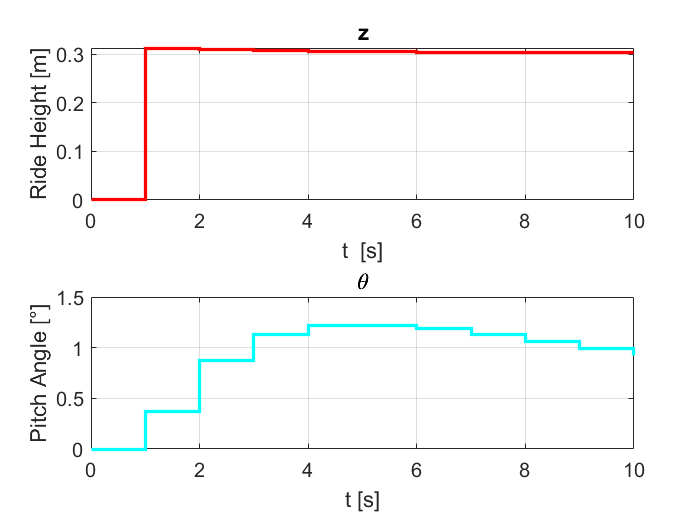

%% In property inspector choose fontsize apprpx 34, gridalpha 0.6, and linewidth approx 8
%Subplot 1 for z
figure,
xplot_45 = [x(4,:)' x(5,:)'];
% Subplot 1 for 'Height [m]' corresponding to 'z'
subplot(2,1,1); % Creates a subplot in a 2x1 grid, at position 1
stairs(0:T_sim, xplot_45(:,1),'LineWidth',2,'Color','r'); % Assuming xplot_45(:,2) corresponds to 'z'
ylabel('Ride Height [m]');
xlabel('t  [s]');
grid on;
title('z');
set(gca, 'FontSize', 12);

% Subplot 2 for '\theta'
subplot(2,1,2); % Creates a subplot in a 2x1 grid, at position 2
stairs(0:T_sim, xplot_45(:,2),'LineWidth',2,'Color','c'); % Assuming xplot_45(:,1) corresponds to '\theta'
ylabel('Pitch Angle [°]');
xlabel('t [s]');
grid on;
title('\theta');
set(gca, 'FontSize', 12);

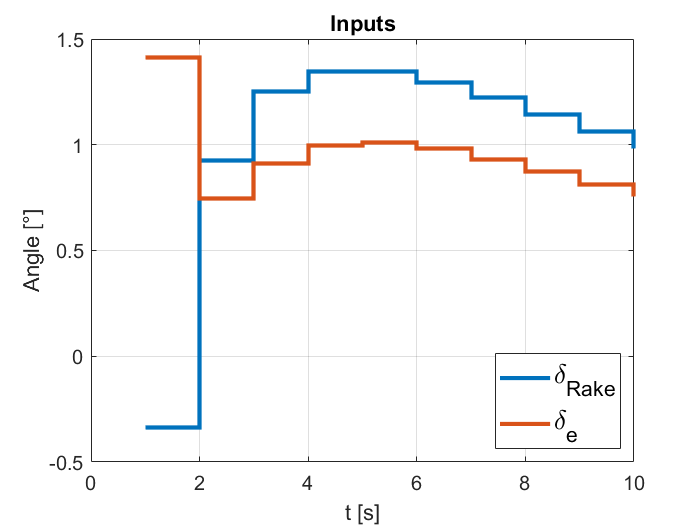



%Input Plot
figure,
u_plot = [u_rec(1,:)' u_rec(2,:)'];
stairs(1:T_sim, u_plot,'LineWidth',2.5),
xlabel('t [s]'), ylabel('Angle [°]'), grid on;
title('Inputs')
lgd = legend('\delta_{Rake}', '\delta_e', 'FontSize', 12);
lgd.Location = 'southeast';
lgd.FontSize = 16;
set(gca, 'FontSize', 12);